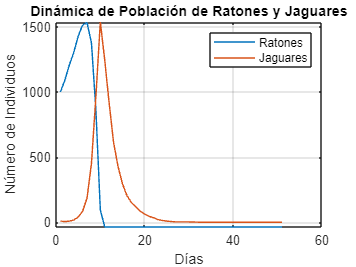

R = 1000;
J = 10;
lambda = 0.1;
mu = 0.001;
v = 0.3;
T = 50;
delta_t = 1;

R_values = [R];
J_values = [J];

for t = 1:T
    lambda1 = max(lambda * R * delta_t, 0);
    lambda2 = max(mu * J * R * delta_t, 0);
    lambda3 = max(v * J * delta_t, 0);

    dN1 = poissrnd(lambda1);
    dN2 = poissrnd(lambda2);
    dN3 = poissrnd(lambda3);

    R = R + dN1 - dN2;
    J = J + dN2 - dN3;

    R_values = [R_values R];
    J_values = [J_values J];
end

figure;
plot(R_values, 'DisplayName', 'Ratones');
hold on;
plot(J_values, 'DisplayName', 'Jaguares');
xlabel('Días');
ylabel('Número de Individuos');
title('Dinámica de Población de Ratones y Jaguares');
legend;
grid on;